# Lecture 1 Introduction to Time Series Analysis

## Introduction to AR and MA Model

% simulate a white noise process
Md_whitenoise = arima;
Md_whitenoise.Constant = 0;
Md_whitenoise.Variance = 1;
summarize(Md_whitenoise)

  arima with properties:

     Description: "ARIMA(0,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 0
               D: 0
               Q: 0
        Constant: 0
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1


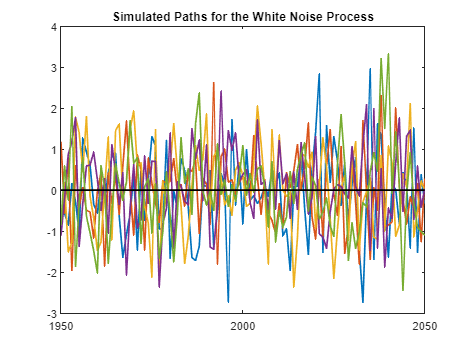


rng(1) % For reproducibility
WN = simulate(Md_whitenoise,101,'NumPaths',5);
plot(1950:2050,WN,1950:2050,zeros(101,1),'k-','LineWidth',1.5)
title('Simulated Paths for the White Noise Process')

% simulate a AR(1) model with rho = 0.8
AR1_1 = arima(1,0,0);
AR1_1.Constant = 0;
AR1_1.Variance = 1;
AR1_1.AR = {0.8};
summarize(AR1_1)

  arima with properties:

     Description: "ARIMA(1,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 0
               Q: 0
        Constant: 0
              AR: {0.8} at lag [1]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1


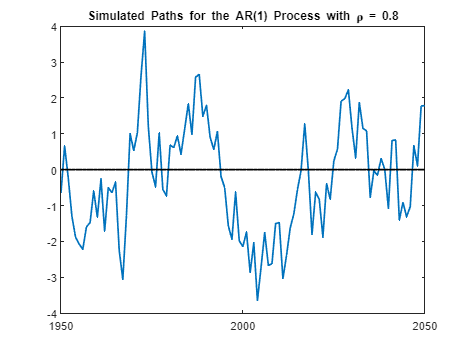


rng(1) % For reproducibility
AR1_Y1 = simulate(AR1_1,101);
plot(1950:2050,AR1_Y1,1950:2050,zeros(101,1),'k-','LineWidth',1.5)
title('Simulated Paths for the AR(1) Process with \rho = 0.8')

The error message “the non-seasonal autoregressive polynomial is unstable” indicates that some of the eigenvalues of the AR part of the series are outside the unit circle, hence non-stationarity. 

Similarly, the error “the non-seasonal moving average polynomial is non-invertible” shows explosion of the MA roots, hence non-invertibility.

Practically it is not a good idea to fit a high-order ARMA model. It might require a huge sample size to provide a good estimate on a ARMA(3,3) model, even if the data are simulated from the true model. To avoid those error messages, be parsimonious in model specification, say ARMA(1,1). If you really want a high-order model, you may consider informative priors to shrink the coefficients.

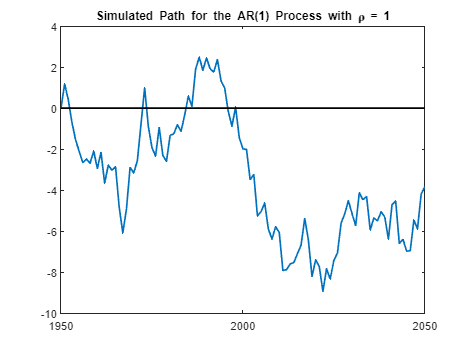

% simulate a AR(1) model with rho = 1, unstable so cannot use arima
AR1_2 = zeros(1,101);
rng(1) % For reproducibility
error1 = randn(1,101);
for i = 2:101
    AR1_2(i) = 1.*AR1_2(i-1)+error1(i);
end
plot(1950:2050,AR1_2,1950:2050,zeros(101,1),'k-','LineWidth',1.5)
title('Simulated Path for the AR(1) Process with \rho = 1')

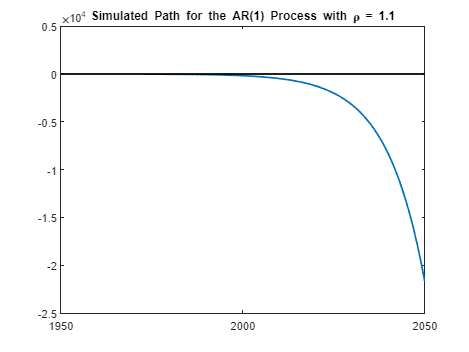

% simulate a AR(1) model with rho = 1.1, unstable so cannot use arima
AR1_3 = zeros(1,101);
rng(1) % For reproducibility
error1 = randn(1,101);
for i = 2:101
    AR1_3(i) = 1.1.*AR1_3(i-1)+error1(i);
end
plot(1950:2050,AR1_3,1950:2050,zeros(101,1),'k-','LineWidth',1.5)
title('Simulated Path for the AR(1) Process with \rho = 1.1')

% simulate a AR(1) model with rho = -0.8
AR1_4 = arima(1,0,0);
AR1_4.Constant = 0;
AR1_4.Variance = 1;
AR1_4.AR = {-0.8};
summarize(AR1_4)

  arima with properties:

     Description: "ARIMA(1,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 0
               Q: 0
        Constant: 0
              AR: {-0.8} at lag [1]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1


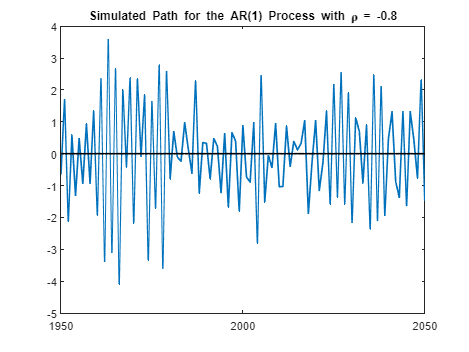


rng(1) % For reproducibility
AR1_Y4 = simulate(AR1_4,101);
plot(1950:2050,AR1_Y4,1950:2050,zeros(101,1),'k-','LineWidth',1.5)
title('Simulated Path for the AR(1) Process with \rho = -0.8')

% simulate a AR(2) model rho_1 = 1.5 and rho_2 = -0.9
AR2_1 = arima(2,0,0);
AR2_1.Constant = 0;
AR2_1.Variance = 1;
AR2_1.AR = {1.5 -0.9};
summarize(AR2_1)

  arima with properties:

     Description: "ARIMA(2,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 2
               D: 0
               Q: 0
        Constant: 0
              AR: {1.5 -0.9} at lags [1 2]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1


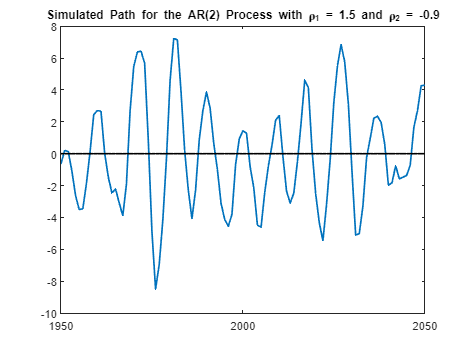


rng(1) % For reproducibility
AR2_Y1 = simulate(AR2_1,101);
plot(1950:2050,AR2_Y1,1950:2050,zeros(101,1),'k-','LineWidth',1.5)
title('Simulated Path for the AR(2) Process with \rho_1 = 1.5 and \rho_2 = -0.9')

% simulate a MA(1) model with theta = 0.8
MA1_1 = arima(0,0,1);
MA1_1.Constant = 0;
MA1_1.Variance = 1;
MA1_1.MA = {0.8};
summarize(MA1_1)

  arima with properties:

     Description: "ARIMA(0,0,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 0
               D: 0
               Q: 1
        Constant: 0
              AR: {}
             SAR: {}
              MA: {0.8} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1


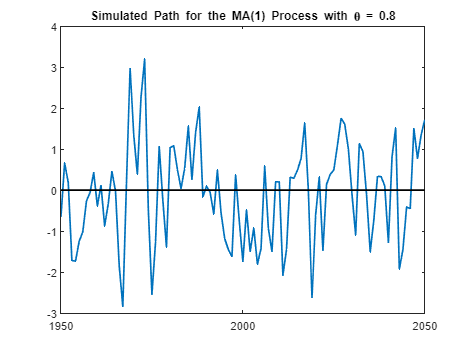


rng(1) % For reproducibility
MA1_Y1 = simulate(MA1_1,101);
plot(1950:2050,MA1_Y1,1950:2050,zeros(101,1),'k-','LineWidth',1.5)
title('Simulated Path for the MA(1) Process with \theta = 0.8')

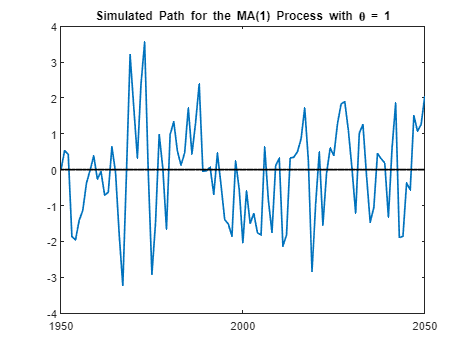

% simulate a MA(1) model with theta = 1, non-invertible
MA1_2 = zeros(1,101);
rng(1) 
error1 = randn(1,101);
for i = 2:101
    MA1_2(i) = error1(i) + 1.*error1(i-1);
end
plot(1950:2050,MA1_2,1950:2050,zeros(101,1),'k-','LineWidth',1.5)
title('Simulated Path for the MA(1) Process with \theta = 1')

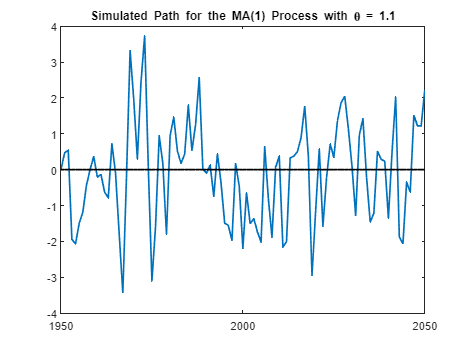

% simulate a MA(1) model with theta = 1.1, non-invertible
MA1_3 = zeros(1,101);
rng(1) 
error1 = randn(1,101);
for i = 2:101
    MA1_3(i) = error1(i) + 1.1.*error1(i-1);
end
plot(1950:2050,MA1_3,1950:2050,zeros(101,1),'k-','LineWidth',1.5)
title('Simulated Path for the MA(1) Process with \theta = 1.1')

% simulate a MA(1) model with theta = -0.8
MA1_4 = arima(0,0,1);
MA1_4.Constant = 0;
MA1_4.Variance = 1;
MA1_4.MA = {-0.8};
summarize(MA1_4)

  arima with properties:

     Description: "ARIMA(0,0,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 0
               D: 0
               Q: 1
        Constant: 0
              AR: {}
             SAR: {}
              MA: {-0.8} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1


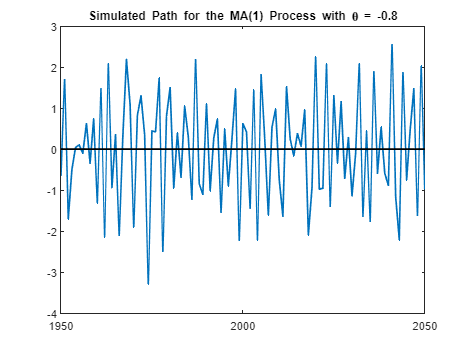


rng(1) % For reproducibility
MA1_Y4 = simulate(MA1_4,101);
plot(1950:2050,MA1_Y4,1950:2050,zeros(101,1),'k-','LineWidth',1.5)
title('Simulated Path for the MA(1) Process with \theta = -0.8')

## Forecasting AR and MA Model

ddddddd




































